# Uge 6

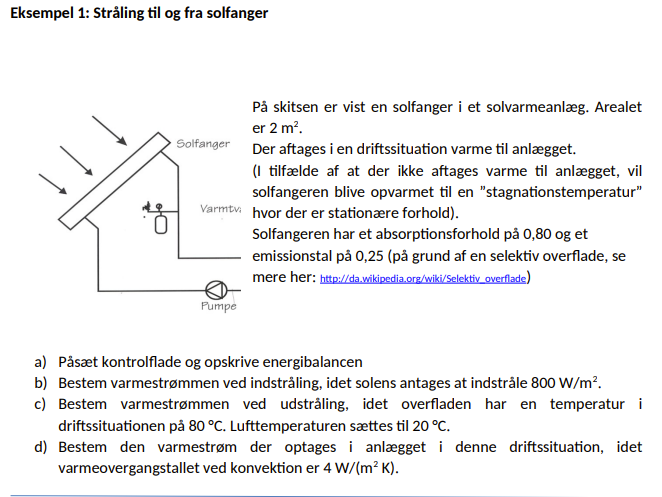

clc; clear all;
u = symunit;

% Opgave 12

boltz = 5.67 * u.W/(u.m^2*u.K^4);  % Side 324

% Solfanger data
A = 2*u.m^2;

alpha = 0.8;    % Absorptionsforhold
epsilon = 0.25; % Emissionstal for solen

sol = 800 * u.W/u.m^2; % q_sol

% Opgave b
phi_ind = alpha * sol * A % Solens indstråling på pladens areal med sit absorptionsforhold

$$phi\_ind = 1280\,W$$



% Opgave c
Cs = epsilon * boltz;       % Strålingskonstanten side 326 [9.53]

T_over = (273.15 + 80)*u.K;
T_luft = (273.15 + 20)*u.K;

phi_ud = Cs*A*(T_over/100)^4;       % [9.51] men kun 1 overflade, derfor ingen T2
phi_ud = vpa(unitConvert(phi_ud,u.W),3)

$$phi\_ud = 441.0\,W$$


% Opgave d
alpha_konv = 4 * u.W/(u.m^2 * u.K);

phi_konv = alpha_konv * A * (T_over - T_luft);
phi_konv = vpa(unitConvert(phi_konv,u.W),3)

$$phi\_konv = 480.0\,W$$


phi_total = vpa(unitConvert(phi_ind - phi_konv - phi_ud, u.W),3)

$$phi\_total = 359.0\,W$$

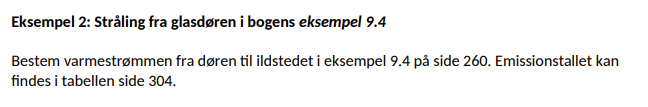

clc; clear all;
u = symunit;

boltz = 5.67 * u.W/(u.m^2*u.K^4);  % Side 324

l = 0.71*u.m;
h = 1.02*u.m;
A = l*h;

T_1 = (273.15 + 20)*u.K;
T_2 = (273.15 + 232)*u.K;

% Værdier for glas
epsilon = 0.94;


Cs = epsilon * boltz;
% Varmestrøm
phi_ud = Cs*A*((T_2/100)^4 - (T_1/100)^4);
phi_ud = vpa(unitConvert(phi_ud,u.W),3)

$$phi\_ud = 2230.0\,W$$

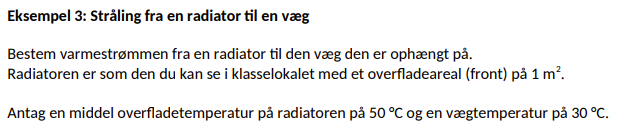

clc; clear all;
u = symunit;

A = 1*u.m^2;

T_1 = (273.15 + 50)*u.K;
T_2 = (273.15 + 30)*u.K;

% Hvid væg
epsilon_wall = 0.92;
epsilon_rad = 0.90;

boltz = 5.67 * u.W/(u.m^2*u.K^4);  % Side 324

Cs = boltz;

C12 = Cs/(1/epsilon_rad + 1/epsilon_wall - 1);
C12 = vpa(C12, 3)

$$C12 = 4.73\,\frac{W}{K^{4}\,m^{2}}$$



% Varmestrøm
phi_ud = C12*A*((T_1/100)^4 - (T_2/100)^4);
phi_ud = vpa(unitConvert(phi_ud,u.W),3)

$$phi\_ud = 116.0\,W$$